# **PROJET D'OPTIMISATION GLOBALE **

**Objectif :** Minimiser le coût de revient du réseau sur une journée d’été.

La variable d'optimisation X est un vecteur ligne 1x48. Les 24 premières colonnes correspondent aux puissances fournies à l'électrolyseur à chaque heure sur les 24h de la journée. Les 24 colonnes suivantes correspondent aux valeurs teta_elec associée à chaque heure de la journée. teta_elec vaut 1 (on) si on active l'électrolyseur et 0 (off) si on ne l'allume pas. 

clear 

data = load ("EteV35Nu10.txt") ;

N = 24 ; %N = nombre d'heures étudiées (On a 2N variables dans notre vecteur d'étude)

%Données à chaque heure 
H = data(:,1) ; %les 24 heures de la journée 
D = data(:,2)'; %vecteur Nx1 des demandes en électricité par heure sur 24h en MW
Peol = data(:,3)'; %vecteur de la puissance éolienne produite par heure en MW 
Ppv = data(:,4)'; %vecteur de la puissance solaire produite par heure en MW
Cext = data(:,end)' ; %Coût de l'électricité du réseau par heure en €/MW
Celec = ones(1,N) ; %Coût de fonctionnement de l'électrolyseur en €/MW

%Autres données
etat_elec = 0.6 ; %Rendement de l'électrolyseur 
Pmax_elec = 30 ;%Pmax de l'électrolyseur par heure en MW 
Pmin_elec = 5 ; %Pmin de l'électrolyseur par heure  en MW

%Quantités minimales d'hydrogène à produire par jour en MW (choisie arbitrairement)
Qjour_H2_ga = linspace(50,200,4); %pour le solver ga
Qjour_H2_pso = [100]; %pour le solver pso 


### **1.Définition de la fonction objectif à minimiser**

La fonction objectif à minimiser est la fonction des coûts de la production électrique sur une journée d'été en fonction des puissances fournies à l'électrolyseur et des variables "on-off" (définissent si l'électrolyseur fonctionne ou pas) à chaque heure. 

Pext = D + Pelec - Peol - Ppv 

Si Pext > 0 --> on achète de l'électricité au réséau

Si Pext < 0 --> on vend de l'électricité au réséau

Si Pext = 0 --> on ne fait rien 

%fonction objectif (prend un vecteur ligne en entrée pour être compatible
%avec le solver ga) 

%Le premier terme de la somme correspond au coût (positif ou négatif) lié à
%l'achat ou la vente d'ékectricité sur le réseau. Le deuxième terme
%correspond au coût de fonctionnement de l'électrolyseur. 

fobj = @(X) (D +X(1,1:N).*X(1,N+1:2*N) - Peol - Ppv)*Cext' + X(1,1:N).*X(1,N+1:2*N)*Celec' ; 


### **2.Définition des contraintes**

%Contraintes inégalités linéaires 

%Contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r soit -Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 <= -𝑄𝐻2𝑗𝑜𝑢r
Aineq_lin1 = [-etat_elec*ones(1,N),zeros(1,N)] ;
% bineq_lin1 : défini dans la boucle for en partie 4 

%Contraintes Pelec > teta_elec*Pmin soit -Pelec + teta_elec*Pmin < 0
Aineq_lin2 = [-eye(N,N),Pmin_elec*eye(N,N)] ;
bineq_lin2 = zeros(N,1) ; 

% Contraintes Pelec <= teta_elec*Pmax soit Pelec- teta_elec*Pmax <= 0
Aineq_lin3 = [eye(N,N),-Pmax_elec*eye(N,N)] ;
bineq_lin3 = zeros(N,1) ; 

%Contrainte inégalité 0 <= teta <= 1  comprise dans les bornes

%Matrices globales contenant toutes les contraintes inégalités linéaires 
Aineq_lin = [Aineq_lin1 ; Aineq_lin2 ; Aineq_lin3 ] ; 
% bineq_lin : défini dans la boucle for en partie 4 

%Contrainte égalité linéaire comprise dans la fonction objectif 
%Pext = D + Pelec - Peol - Ppv (équation 1)

### 3. Définition des bornes

%lb = [Pmin_elec*ones(1,N) , zeros(1,N)] ; 
lb = zeros(1,2*N) ; 
ub = [Pmax_elec*ones(1,N) , ones(1,N)] ; 


### 4. Solver : algo génétique

Attention : le solver considère que la variable d'optimisation est de dimension 1 x nvars (vecteur ligne) mais il sait que cette variable est sous forme de colonne dans l'expression des contraintes (AX = B). Le solver ga effectue la conversion lui-même.

var = length(Qjour_H2_ga);


%Matrice contenant les 24 puissances de l'électrolyseur et les 24 teta pour chaque valeur de Qjour_H2
mat_sol_ga = zeros(2*N,var); 

%Matrice des coûts de fonctionnement de l'électrolyseur pour chaque valeur de Qjour_H2
mat_fval_ga = zeros(var,1);

%Options du solver ga

options_ga=optimoptions('ga') ; 

%options.FunctionTolerance = 1e-50 ; %permet de modifier la tolérance

intcon = [N+1:2*N] ; %on spécifie que les teta sont des variables entières
pop = 200 ; %valeur par défaut selon le cours
options_ga.PopulationSize = pop ; 
options_ga.EliteCount = 0.05*pop ; %Définit le nombre des meilleurs individus 
% qui sont conservés à la génération suivante (0.05 * PopulationSize par defaut)

teta_al = randi([0,1],200,N) ; %création d'une matrice 200xN avec des valeurs de teta aléatoire
%Matrice Init contient les valeurs de la population initiale choisie de
%façon aléatoire. 
%Le premier terme choisit Pelec aléatoirement entre Pmin et Pmax et le
%mutliplie par le teta équivalent.
Init= [randi([Pmin_elec,Pmax_elec],200,N).*teta_al,teta_al];

options_ga.InitialPopulationMatrix = Init ; 

for i = 1:var
    bineq_lin1 = [-Qjour_H2_ga(i)] ;  
    bineq_lin = [bineq_lin1 ; bineq_lin2 ; bineq_lin3] ;
    [sol_ga,fval_ga,exitflag_ga,output_ga,population_ga,scores_ga] = ga(fobj,2*N,Aineq_lin,bineq_lin,[],[],lb,ub,'',intcon, options_ga) ;
    mat_sol_ga(:,i) = sol_ga ; 
    mat_fval_ga(i) = fval_ga;
end

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


### 5. Résultats avec le solver ga

disp('Valeurs journalières de la quantité minimale de H2 à produire (en MW)')

Valeurs journalières de la quantité minimale de H2 à produire (en MW)


disp(Qjour_H2_ga)

    50   100   150   200



disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)


disp(mat_sol_ga(1:N,:))

         0   20.0815         0   18.4016
         0         0   29.9977   30.0000
   28.3744   29.9992   30.0000   29.9997
         0   29.9992   26.9391         0
   27.4615   29.9638   30.0000   29.9948
         0         0   30.0000   29.9938
         0   28.1319   29.9981   28.5779
         0         0    5.0056    5.2294
         0         0         0    5.0061
    7.3798         0         0    5.0034
    4.9990         0         0         0
         0         0         0    5.0070
    4.9990         0         0         0
         0         0    5.0006         0
         0         0   22.1676    5.0028
         0         0    5.0088    5.0019
         0         0         0    6.4353
         0         0         0         0
         0    4.9996         0   17.7606
    5.1122    4.9993    6.6650         0
    5.0057         0         0   26.9842
         0         0    5.0112   28.4520
         0   18.4905         0   26.6872
         0         0   24.2049   29.7945



disp('Les coûts journaliers optimaux pour chaque quantité de H2 (en €)')

Les coûts journaliers optimaux pour chaque quantité de H2 (en €)


disp(mat_fval_ga)

   1.0e+03 *

   -0.0686
    0.4585
    1.1249
    1.9005



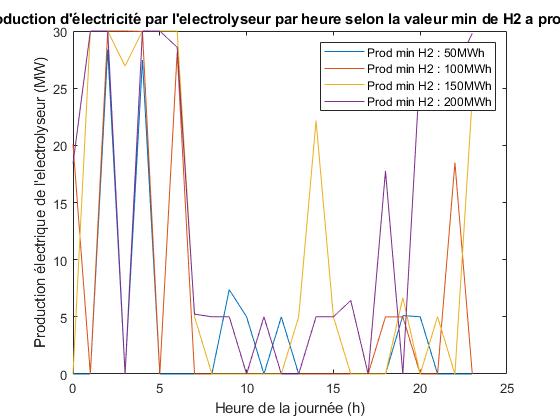

plot(H,mat_sol_ga(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la valeur min de H2 a produire ')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Prod min H2 : ' + string(Qjour_H2_ga) + 'MWh')

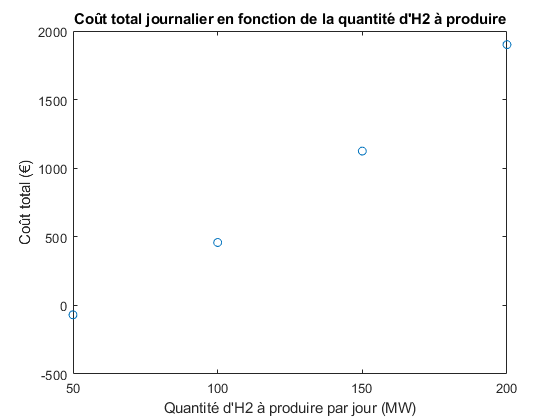


plot(Qjour_H2_ga, mat_fval_ga, 'O')
title("Coût total journalier en fonction de la quantité d'H2 à produire")
xlabel("Quantité d'H2 à produire par jour (MW)")
ylabel("Coût total (€)")

%xlim([0 250])

### 6. Solver : particle swarm

% Ajout des contraines sous forme de pénalités
fobj_pso = @(X) fobj(X) + penalite(X, Qjour_H2_pso, etat_elec, N);
swarm_size = [50, 100, 500] ;
s = length(swarm_size);

mat_sol_pso = zeros(2*N,s) ; 
mat_fval_pso = zeros(1,s) ; 

for j = 1:s
    options_pso= optimoptions('particleswarm',"SwarmSize",swarm_size(j)) ; 
    [sol_pso,fval_pso,exitflag_pso,output_pso] = particleswarm(fobj_pso,2*N,lb,ub,options_pso) ;
    mat_sol_pso(:,j) = sol_pso ; 
    mat_fval_pso(:,j) = fval_pso ; 
end

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


### 7. Résultats avec le solver pso 

disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)


disp(mat_sol_pso(1:N,:))

    0.0603   10.6866    0.0003
   23.6304    5.5311   13.9740
   30.0000   29.7145   29.4735
   30.0000   28.9201   30.0000
   15.7945   28.2508   27.8920
   30.0000   19.4845   30.0000
   29.0072   30.0000   29.6197
   24.2061   21.2849         0
    1.0485   14.7226         0
    5.0119    2.7300    0.2874
         0   29.9519         0
         0    1.6256   28.5396
         0   19.7657         0
    8.7366         0         0
    2.2970    1.3372         0
   10.2654         0    5.0768
   30.0000    0.5015   30.0000
    7.4637         0    2.3526
         0         0   29.2308
         0   15.5397         0
         0         0         0
         0         0    0.2643
   27.2478         0         0
   30.0000   22.4242         0



disp('Les coûts journaliers optimaux pour chaque taille de population initiale (en €)')

Les coûts journaliers optimaux pour chaque taille de population initiale (en €)


disp(mat_fval_pso)

   1.0e+10 *

    1.0000    1.0000    1.0000



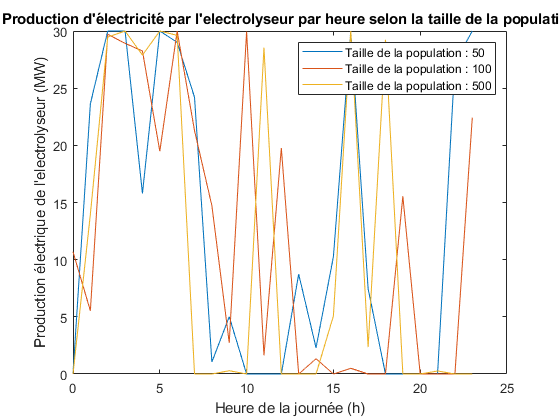

plot(H,mat_sol_pso(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la taille de la population')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Taille de la population : ' + string(swarm_size))

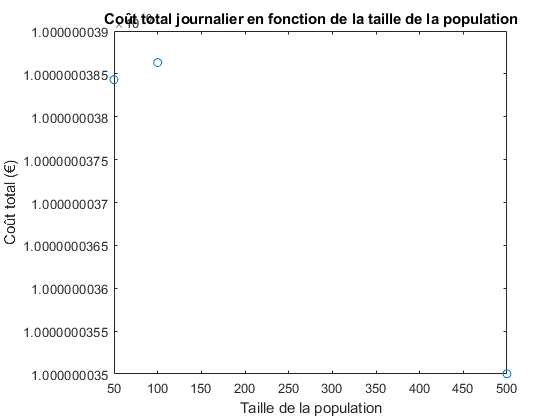


plot(swarm_size, mat_fval_pso, 'O')
title("Coût total journalier en fonction de la taille de la population")
xlabel("Taille de la population")
ylabel("Coût total (€)")

%xlim([0 600])

### Fonction pénalité du solver particle swarm 

Cette fonction permet de traduire les contraintes Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r et teta est un entier. 

function [c] = penalite(X, Qjour_H2, etat, N)
%on choisit q=2 arbitrairement 
q=2 ; 

%Pénalité traduisant la contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r
c = max(0, Qjour_H2 - etat*X(1:N)*X(N+1:2*N)')^q;

%Nous avons imposé dans les bornes du problème que : 0<teta<1. 
%Pour s'assurer que teta soit un entier, on impose qu'il vale soit 0 soit 1. 
%Pénalité si les teta ne valent pas 0 ou 1 : 
c2 = X(N+1:2*N)*(X(N+1:2*N)'-1); %c2 ne vaut 0 que si les teta valent O ou 1 

c = c + (abs(c2)>=1e-5)*1e10 ; 

%Les teta ne valent jamais vraiment 0, on prend donc la valeur 1e-5 pour approcher le 0.

%--> Si (abs(c2)>=1e-5) est vérifié, cela veut dire que c2 n'est pas
%nul et donc que certains tetas sont différents de 0 ou 1. 
% (abs(c2)=>1e-5) prend donc la valeur 1, qu'on mutliplie par 1e10 pour lourdement
%pénaliser.
%--> Si (abs(c2)>=1e-5) n'est pas vérifié, cela veut dire que c2 est inférieur à 1e-5, c2 est nul,
% et donc les tetas valent tous 0 ou 1. 
%(abs(c2)>=1e-5) prend la valeur 0 qu'on multiplie par 1e10, il n'y a pas de pénalité. 

end